## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

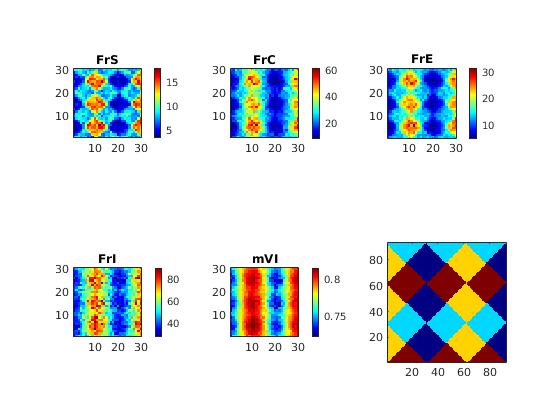

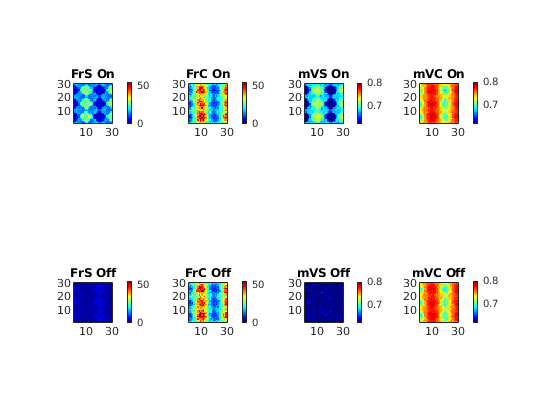

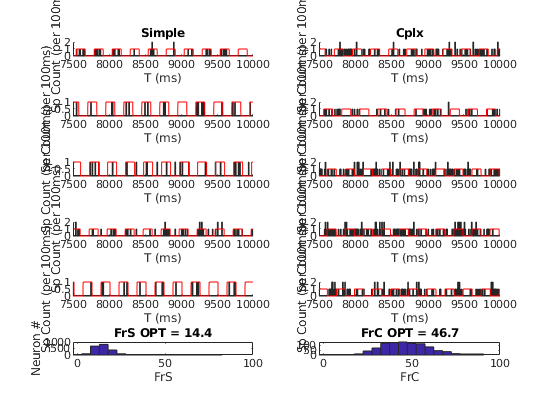

load("AllMFPixPara_Paper2TuneFig1V4.mat")

%load("AllMFPixPara_Paper2Tune.mat")

DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
%FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);
fLDE_OPT = load([DataFolder 'Paper2_LDE3_Fig1V4.mat'],'f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load([DataFolder 'Paper2_LDE2_Fig1V4.mat'],'f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load([DataFolder 'Paper2_LDE1_Fig1V4.mat'],'f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~(isempty(fLDE_OPT{LDEInd}) || size(fLDE_OPT{LDEInd},2)<25)
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_opt(FrLDE_opt<0) = eps;
FrLDE_obl(FrLDE_obl<0) = eps;
FrLDE_ort(FrLDE_ort<0) = eps;
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
    (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
    (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
    (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

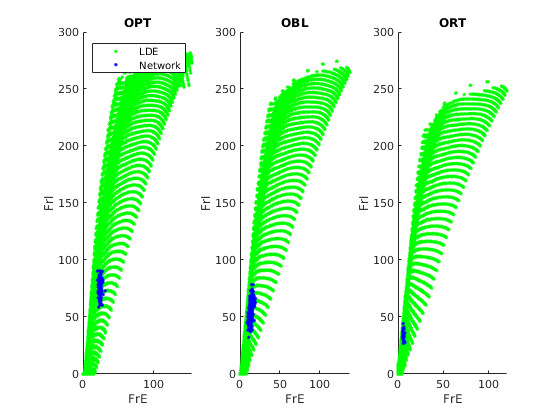

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
%scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
%scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
%scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

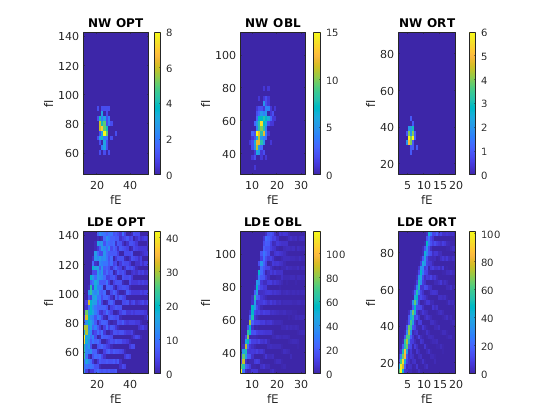


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

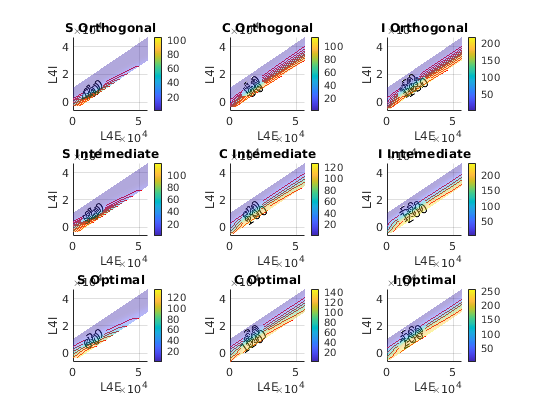

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
load(['Paper2_LDE1_Fig1V4.mat'])
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);


figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['Paper2_LDE' num2str(Ctgr) '_Fig1V4.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    FrLDE(FrLDE<0) = eps;
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true);

    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true);

    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true);
end

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

Maybe linear extrapolation?

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 3; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

PixL6Ctgr = LGNIndSpat(L6SFilt,unique(L6S_Drive),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(PhaseFRS(OD_S)',unique(PhaseFRS(OD_S)),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
% Classify Input for each pixel
% Get input spatial pattern for 3*3 and make a larger one

% PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
% PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixInptCtgr,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY)

% CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
% cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
% colormap(CtgrMap)

Give an intial condition, Now start

try a dot product here

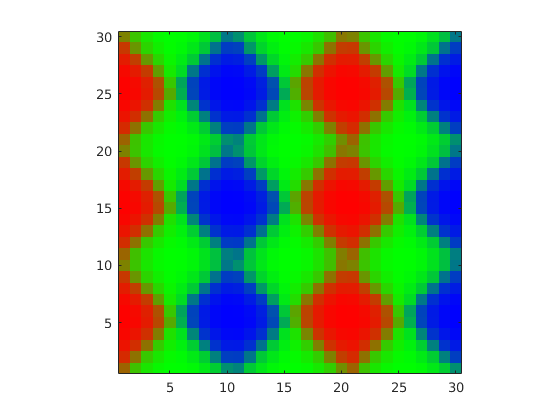

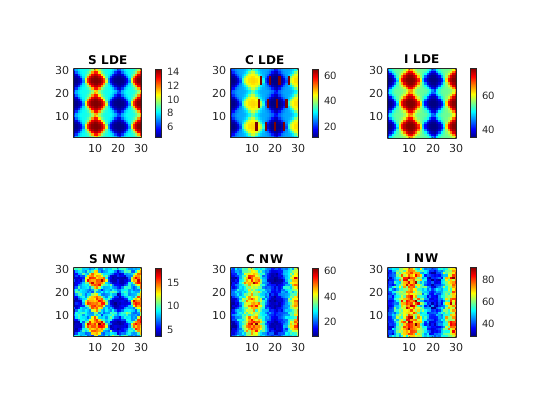

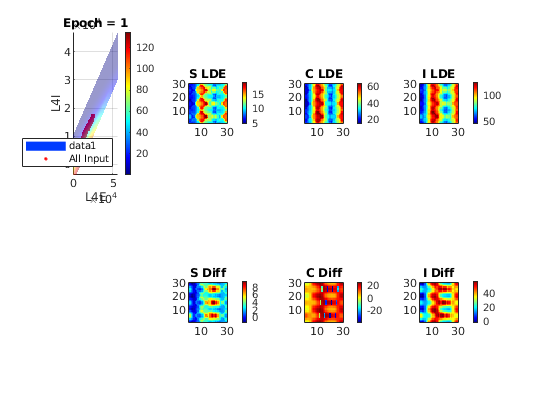

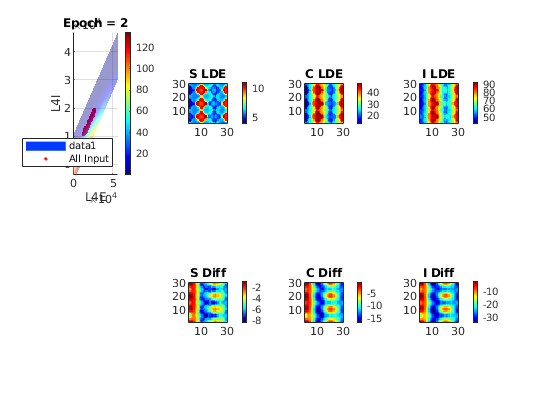

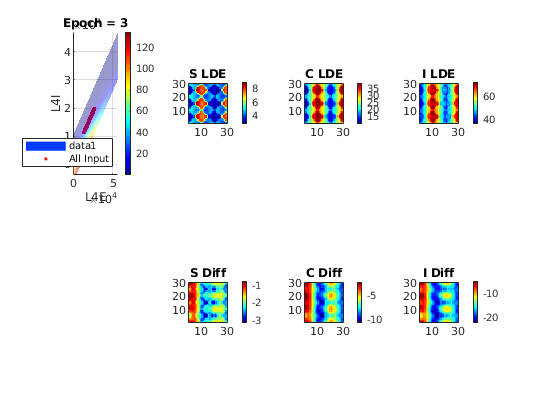

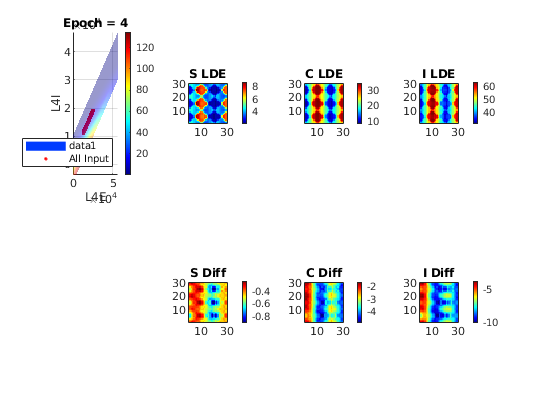

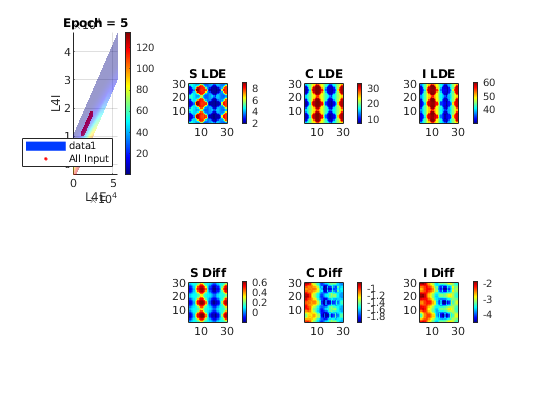

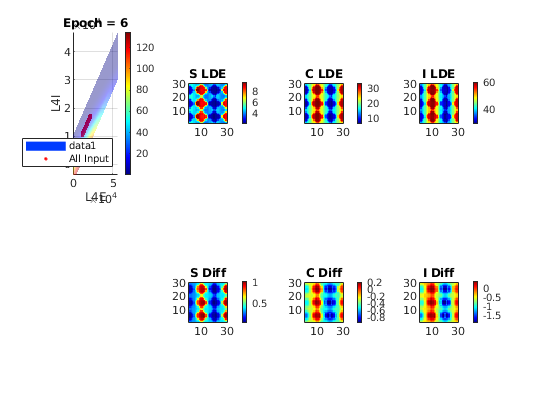

ORTPixLar = PixInptCtgr(:,1) == 1;
OBLPixLar = PixInptCtgr(:,2) == 1;
OPTPixLar = PixInptCtgr(:,3) == 1;
MeanFrCtry = @(x1) [mean(x1(ORTPix)),mean(x1(OBLPix)),mean(x1(OPTPix))];

LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
% LDEIni.S = ORTPix*mean(FrSPixVec(ORTPix)) + OBLPix*mean(FrSPixVec(OBLPix)) + ...
%            OPTPix*mean(FrSPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrSPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrSPixVec(OPTOBLBd_Pix));
% LDEIni.C = ORTPix*mean(FrCPixVec(ORTPix)) + OBLPix*mean(FrCPixVec(OBLPix)) + ...
%            OPTPix*mean(FrCPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrCPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrCPixVec(OPTOBLBd_Pix));
% LDEIni.I = ORTPix*mean(FrIPixVec(ORTPix)) + OBLPix*mean(FrIPixVec(OBLPix)) + ...
%            OPTPix*mean(FrIPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrIPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrIPixVec(OPTOBLBd_Pix));

for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    figure('Name','LDE Iteration')
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S  - diag(C_SS_mean).*LDEUse.S + ...
        C_CS_mean*LDEUse.S  - diag(C_CS_mean).*LDEUse.S + ...
        C_IS_mean*LDEUse.S  - diag(C_IS_mean).*LDEUse.S + ...
        C_SC_mean*LDEUse.C  - diag(C_SC_mean).*LDEUse.C + ...
        C_CC_mean*LDEUse.C  - diag(C_CC_mean).*LDEUse.C + ...
        C_IC_mean*LDEUse.C  - diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I  - diag(C_SI_mean).*LDEUse.I + ...
        C_CI_mean*LDEUse.I  - diag(C_CI_mean).*LDEUse.I + ...
        C_II_mean*LDEUse.I  - diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    subplot 241
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
    hold on
    scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
    %     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
    %     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
    %     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
    %     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
    %     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
    legend('Location','southeast')
    title(sprintf('Epoch = %d', Epc))
    hold off
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
        L4EUse,L4IUse,LDEUse.S,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
        L4EUse,L4IUse,LDEUse.C,...
        PixInptCtgr);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
        L4EUse,L4IUse,LDEUse.I,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
    subplot 242
    ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
    subplot 243
    ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
    subplot 244
    ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
    subplot 246
    ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
    subplot 247
    ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
    subplot 248
    ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
    drawnow
    pause(0.5)
end

One more fig for diff

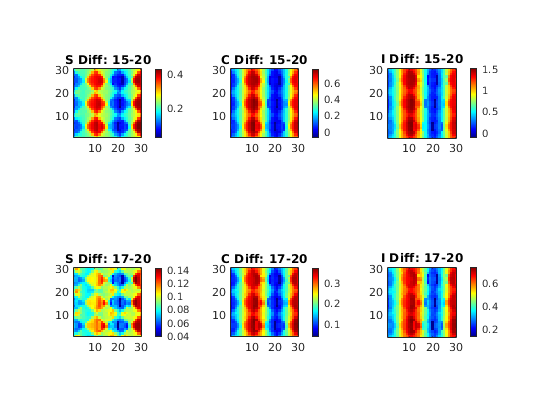

figure('Name','epoch diff')
subplot 231
Ep1 = 15; Ep2 = 17; Ep3 = 20;
ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
subplot 232
ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
subplot 233
ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))

subplot 234
ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
subplot 235
ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
subplot 236
ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

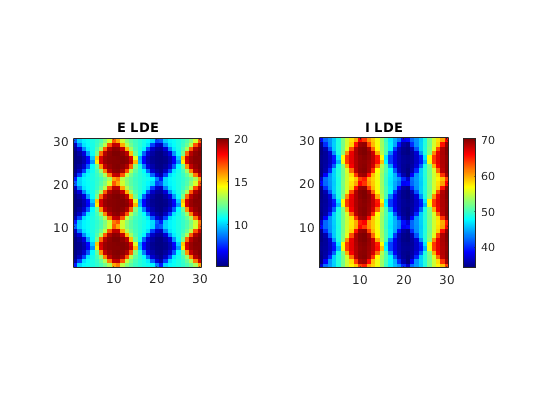


figure('Name','EImap')
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')

 Compute Frs

LDENames = fieldnames(LDEOut)

LDENames = 3×1 cell array
    {'S'}
    {'C'}
    {'I'}


for Nid = 1:length(LDENames)
    CurrField = LDEOut.(LDENames{Nid});
    CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
    CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
    LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
    MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
end

ans =     3.7294    6.3236   11.7781


ans =     8.5867   23.4758   38.1576


ans =    34.9337   51.1832   69.3771


## 4. Comparison between MF+V and LIF-only

L4lifSE = C_SS_Pixel_Us*FrSPixVec + C_SC_Pixel_Us*FrCPixVec;
L4lifSI = C_SI_Pixel_Us*FrIPixVec ;
L4lifCE = C_CS_Pixel_Us*FrSPixVec + C_CC_Pixel_Us*FrCPixVec;
L4lifCI = C_CI_Pixel_Us*FrIPixVec ;
L4lifIE = C_IS_Pixel_Us*FrSPixVec + C_IC_Pixel_Us*FrCPixVec;
L4lifII = C_II_Pixel_Us*FrIPixVec ;
L4localSE = diag(C_SS_Pixel_Us).*FrSPixVec + diag(C_SC_Pixel_Us).*FrCPixVec;
L4localSI = diag(C_SI_Pixel_Us).*FrIPixVec ;
L4localCE = diag(C_CS_Pixel_Us).*FrSPixVec + diag(C_CC_Pixel_Us).*FrCPixVec;
L4localCI = diag(C_CI_Pixel_Us).*FrIPixVec ;
L4localIE = diag(C_IS_Pixel_Us).*FrSPixVec + diag(C_IC_Pixel_Us).*FrCPixVec;
L4localII = diag(C_II_Pixel_Us).*FrIPixVec ;
L4EmfvUse = C_SS_Pixel_Us*FrSPixVec  - diag(C_SS_Pixel_Us).*FrSPixVec + ...
            C_CS_Pixel_Us*FrSPixVec  - diag(C_CS_Pixel_Us).*FrSPixVec + ...
            C_IS_Pixel_Us*FrSPixVec  - diag(C_IS_Pixel_Us).*FrSPixVec + ...
            C_SC_Pixel_Us*FrCPixVec  - diag(C_SC_Pixel_Us).*FrCPixVec + ...
            C_CC_Pixel_Us*FrCPixVec  - diag(C_CC_Pixel_Us).*FrCPixVec + ...
            C_IC_Pixel_Us*FrCPixVec  - diag(C_IC_Pixel_Us).*FrCPixVec ;
L4ImfvUse = C_SI_Pixel_Us*FrIPixVec  - diag(C_SI_Pixel_Us).*FrIPixVec + ...
            C_CI_Pixel_Us*FrIPixVec  - diag(C_CI_Pixel_Us).*FrIPixVec + ...
            C_II_Pixel_Us*FrIPixVec  - diag(C_II_Pixel_Us).*FrIPixVec ;

Now consider a pixel containing 3 neurons: S C I

Pick up 10 pixels

%InputCtgrList = [1,1, 1,  2,  2,  2,   3,  3,   3];
%PixRow = [5,5,25,  1,10,20,  5,15,5 ];
PixRow = randi([1,30],50,1);
%PixCol = [1,20,20, 15,15,26, 10,10,29];
PixCol = randi([1,30],50,1);
PixIndList = (PixCol-1)*N_HC*NPixY +  PixRow ;% [7,55,615,180,450,645, 565,326, 276];
VRcdAll = cell(size(PixIndList));
SpRcdAll = cell(size(PixIndList));
FrRcdAve = zeros(length(PixIndList),3);

for LIFtestInd = 1:length(PixIndList)
%InputCtgr = InputCtgrList(LIFtestInd); 
PixInd = PixIndList(LIFtestInd); % pixel and input category

FL6_One = unique(L6Ord_F)/1e3;
rL6SU = L6S_Pixel(PixInd);
rL6CU = L6C_Pixel(PixInd);
rL6IU = L6I_Pixel(PixInd);
L4SE = L4lifSE(PixInd)/1e3*(1-p_EEFail); L4CE = L4lifCE(PixInd)/1e3*(1-p_EEFail); L4IE = L4lifIE(PixInd)/1e3;
L4SI = L4lifSI(PixInd)/1e3;              L4CI = L4lifCI(PixInd)/1e3;              L4II = L4lifII(PixInd)/1e3;

LIFSimuT = 50*1e3; TimeFrac = 1/(LIFSimuT/1e3)/LGNFreq;
lgn_Events    = PoissonInputForNetwork(3, 45*[N_Slgn;N_Clgn;N_Ilgn]/1e3 ,LIFSimuT*TimeFrac,dt,true);
AmbPix_Events = PoissonInputForNetwork(3,[rS_amb;rC_amb;rI_amb],LIFSimuT*TimeFrac,dt,true);
L6Pix_Events  = PoissonInputForNetwork(3,[rL6SU; rL6CU; rL6IU], LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsE = PoissonInputForNetwork(3,[L4SE; L4CE; L4IE],LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsI = PoissonInputForNetwork(3,[L4SI; L4CI; L4II],LIFSimuT*TimeFrac,dt,true);
gL = [gL_E*ones(2,1); gL_I*ones(1)];

Can precompute all Gs...

% Now adjust lgn to S
lgn_SOnOff = [0.045, 0.0675, 0.09;
              0.045, 0.0225, 0.00];
lgn_Slif = [lambda_SOn_Pixel';lambda_SOff_Pixel'];
lgn_Slifort = mean(mean(lgn_Slif))*ones(2,1);

lgnAdj = lgn_Slif(:,PixInd)./lgn_Slifort;
lgnAdjU = reshape(repmat(lgnAdj,1,floor(size(L4Pix_EventsE,2)/2))', 1, 2*floor(size(L4Pix_EventsE,2)/2));

Disp some # of spikes

sprintf('#L6 = %.4f', sum(FL6_One.*PixL6Ctgr(PixInd,:)))
sprintf('#L4SE total = %.4f, #L4SI total = %.4f',L4lifSE(PixInd)/1e3,L4lifSI(PixInd)/1e3)
sprintf('#L4CE total = %.4f, #L4CI total = %.4f',L4lifCE(PixInd)/1e3,L4lifCI(PixInd)/1e3)
sprintf('#L4IE total = %.4f, #L4II total = %.4f',L4lifIE(PixInd)/1e3,L4lifII(PixInd)/1e3)
sprintf('#L4SE local = %.4f, #L4SI local = %.4f',L4localSE(PixInd)/1e3,L4localSI(PixInd)/1e3)
sprintf('#L4CE local = %.4f, #L4CI local = %.4f',L4localCE(PixInd)/1e3,L4localCI(PixInd)/1e3)
sprintf('#L4IE local = %.4f, #L4II local = %.4f',L4localIE(PixInd)/1e3,L4localII(PixInd)/1e3)
% For each cycle, initiate a new start
TCyc = floor(1/TimeFrac);
VRcdCyc = cell(TCyc,1);
SpRcdCyc = cell(TCyc,1);

RefTimer = zeros(3, 1); % initiate the timer of ref
vt = zeros(3, 1); 
tic
for TInt = 1:TCyc
    VRcd = zeros(size(L4Pix_EventsE));
    SpLIF = zeros(3, 1);

    % New Gs
    lgnPix_Events = lgn_Events(:,randperm(size(lgn_Events,2)));
    lgnPix_Events(1,1:length(lgnAdjU)) = lgnPix_Events(1,1:length(lgnAdjU)).*lgnAdjU;

    winAMPA = 0:dt:tau_ampa_D*3;
    winNMDA = 0:dt:tau_nmda_D*3;
    winGABA = 0:dt:tau_gaba_D*3;
    KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
    KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
    KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
    KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
    KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
    KerGABA = KerGABA / (sum(KerGABA)*dt);
    % Incorporate L4 and other input
    ampaInp = single([S_Elgn * lgnPix_Events(1:2,:);            S_Ilgn * lgnPix_Events(3,:)]...
        +  S_amb  * AmbPix_Events ... % S_amb identical for E and I
        + [S_EL6  * L6Pix_Events(1:2,:) * rhoE_ampa; S_IL6 * L6Pix_Events(3,:) * rhoI_ampa]...
        + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_ampa; S_IE * L4Pix_EventsE(3,:) * rhoI_ampa]);
    nmdaInp = single([S_EL6  * L6Pix_Events(1:2,:) * rhoE_nmda; S_IL6 * L6Pix_Events(3,:) * rhoI_nmda]...
        + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_nmda; S_IE * L4Pix_EventsE(3,:) * rhoI_nmda]);
    gabaInp = single([S_EI * L4Pix_EventsI(1:2,:);             S_II * L4Pix_EventsI(3,:)] );
    %% Precompute All Conductances: Speed up by ifft/fft
    n = size(ampaInp,2);
    GAMPA = ifft(fft(ampaInp',n) .* repmat(fft(KerAMPA',n),1,3))';
    GNMDA = ifft(fft(nmdaInp',n) .* repmat(fft(KerNMDA',n),1,3))';
    GGABA = ifft(fft(gabaInp',n) .* repmat(fft(KerGABA',n),1,3))';

    GE = GAMPA + GNMDA;  GI = GGABA;
    
    for tInd = 1:size(L4Pix_EventsE,2)
        % Firstly, refrectory neurons get out if timer reachs t_ref
        RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
        vt(RefTimer>=tau_ref) = 0;
        RefTimer(RefTimer>=tau_ref) = 0;

        ov  = vt + dt*(-gL.*vt - GE(:,tInd).*(vt-Ve) - GI(:,tInd).*(vt-Vi));
        SpNow = single(ov>=1);
        ov(ov>=1) = nan;
        VRcd(:,tInd) = ov;
        % Compute meanV
            SpLIF = SpLIF + SpNow;
        % Transfer variables
        vt = ov;
    end
    VRcdCyc{TInt} = VRcd;
    SpRcdCyc{TInt} = SpLIF;
end
toc
VRcdAll{LIFtestInd} = VRcdCyc;
SpRcdAll{LIFtestInd} = SpRcdCyc;
SpRcdMat = cell2mat(SpRcdCyc')';
FrRcdAve(LIFtestInd,:) = mean(SpRcdMat(10:end,:))*LGNFreq; % The actual firing rates
%LDEresults = zeros(length(FrSPixVec),3);
end

ans = '#L6 = 0.0492'

ans = '#L4SE total = 3.7487, #L4SI total = 6.1326'

ans = '#L4CE total = 4.9203, #L4CI total = 6.1261'

ans = '#L4IE total = 16.2260, #L4II total = 5.9230'

ans = '#L4SE local = 0.0591, #L4SI local = 0.3511'

ans = '#L4CE local = 0.0835, #L4CI local = 0.2270'

ans = '#L4IE local = 0.3116, #L4II local = 0.2932'

Elapsed time is 3.515704 seconds.


ans = '#L6 = 0.0149'

ans = '#L4SE total = 1.7783, #L4SI total = 3.2438'

ans = '#L4CE total = 2.3787, #L4CI total = 3.2840'

ans = '#L4IE total = 7.9268, #L4II total = 3.2206'

ans = '#L4SE local = 0.0164, #L4SI local = 0.1155'

ans = '#L4CE local = 0.0266, #L4CI local = 0.1046'

ans = '#L4IE local = 0.0804, #L4II local = 0.0856'

Elapsed time is 3.435588 seconds.


ans = '#L6 = 0.0128'

ans = '#L4SE total = 1.7920, #L4SI total = 3.2606'

ans = '#L4CE total = 2.4176, #L4CI total = 3.2072'

ans = '#L4IE total = 8.1649, #L4II total = 3.1851'

ans = '#L4SE local = 0.0205, #L4SI local = 0.1311'

ans = '#L4CE local = 0.0272, #L4CI local = 0.1785'

ans = '#L4IE local = 0.0833, #L4II local = 0.1286'

Elapsed time is 3.441441 seconds.


ans = '#L6 = 0.0300'

ans = '#L4SE total = 2.6201, #L4SI total = 4.5195'

ans = '#L4CE total = 3.4955, #L4CI total = 4.6126'

ans = '#L4IE total = 11.5927, #L4II total = 4.3977'

ans = '#L4SE local = 0.0460, #L4SI local = 0.2324'

ans = '#L4CE local = 0.0640, #L4CI local = 0.2243'

ans = '#L4IE local = 0.2088, #L4II local = 0.1971'

Elapsed time is 3.464561 seconds.


ans = '#L6 = 0.0292'

ans = '#L4SE total = 2.3260, #L4SI total = 4.0890'

ans = '#L4CE total = 3.1790, #L4CI total = 4.1404'

ans = '#L4IE total = 10.3503, #L4II total = 4.0854'

ans = '#L4SE local = 0.0593, #L4SI local = 0.1423'

ans = '#L4CE local = 0.0772, #L4CI local = 0.1302'

ans = '#L4IE local = 0.2129, #L4II local = 0.0837'

Elapsed time is 3.407310 seconds.


ans = '#L6 = 0.0328'

ans = '#L4SE total = 2.9196, #L4SI total = 4.9480'

ans = '#L4CE total = 3.8896, #L4CI total = 4.8860'

ans = '#L4IE total = 13.1072, #L4II total = 4.9027'

ans = '#L4SE local = 0.0436, #L4SI local = 0.2152'

ans = '#L4CE local = 0.0604, #L4CI local = 0.2013'

ans = '#L4IE local = 0.2089, #L4II local = 0.1342'

Elapsed time is 3.508000 seconds.


ans = '#L6 = 0.0409'

ans = '#L4SE total = 3.6245, #L4SI total = 5.9124'

ans = '#L4CE total = 4.7988, #L4CI total = 5.9121'

ans = '#L4IE total = 15.8105, #L4II total = 5.7908'

ans = '#L4SE local = 0.0468, #L4SI local = 0.2602'

ans = '#L4CE local = 0.0715, #L4CI local = 0.2760'

ans = '#L4IE local = 0.2642, #L4II local = 0.2029'

Elapsed time is 3.503195 seconds.


ans = '#L6 = 0.0490'

ans = '#L4SE total = 3.6999, #L4SI total = 6.0901'

ans = '#L4CE total = 4.9364, #L4CI total = 6.0532'

ans = '#L4IE total = 16.3839, #L4II total = 6.0312'

ans = '#L4SE local = 0.1110, #L4SI local = 0.2518'

ans = '#L4CE local = 0.1003, #L4CI local = 0.2507'

ans = '#L4IE local = 0.3061, #L4II local = 0.2328'

Elapsed time is 3.507001 seconds.


ans = '#L6 = 0.0252'

ans = '#L4SE total = 1.9938, #L4SI total = 3.6668'

ans = '#L4CE total = 2.6868, #L4CI total = 3.6594'

ans = '#L4IE total = 9.0366, #L4II total = 3.6811'

ans = '#L4SE local = 0.0394, #L4SI local = 0.1582'

ans = '#L4CE local = 0.0461, #L4CI local = 0.1965'

ans = '#L4IE local = 0.1534, #L4II local = 0.1396'

Elapsed time is 3.482719 seconds.


ans = '#L6 = 0.0335'

ans = '#L4SE total = 3.1508, #L4SI total = 5.2231'

ans = '#L4CE total = 4.2673, #L4CI total = 5.2865'

ans = '#L4IE total = 13.9448, #L4II total = 5.1612'

ans = '#L4SE local = 0.0441, #L4SI local = 0.2108'

ans = '#L4CE local = 0.0538, #L4CI local = 0.2221'

ans = '#L4IE local = 0.2296, #L4II local = 0.1319'

Elapsed time is 3.507315 seconds.


ans = '#L6 = 0.0149'

ans = '#L4SE total = 2.0060, #L4SI total = 3.6004'

ans = '#L4CE total = 2.7492, #L4CI total = 3.6029'

ans = '#L4IE total = 9.2176, #L4II total = 3.5853'

ans = '#L4SE local = 0.0235, #L4SI local = 0.1072'

ans = '#L4CE local = 0.0299, #L4CI local = 0.1420'

ans = '#L4IE local = 0.0995, #L4II local = 0.1159'

Elapsed time is 3.469894 seconds.


ans = '#L6 = 0.0342'

ans = '#L4SE total = 3.3141, #L4SI total = 5.5318'

ans = '#L4CE total = 4.4969, #L4CI total = 5.5642'

ans = '#L4IE total = 14.6874, #L4II total = 5.3587'

ans = '#L4SE local = 0.0522, #L4SI local = 0.2686'

ans = '#L4CE local = 0.0759, #L4CI local = 0.2608'

ans = '#L4IE local = 0.2284, #L4II local = 0.2391'

Elapsed time is 3.490926 seconds.


ans = '#L6 = 0.0303'

ans = '#L4SE total = 2.4260, #L4SI total = 4.3334'

ans = '#L4CE total = 3.2672, #L4CI total = 4.3574'

ans = '#L4IE total = 11.1839, #L4II total = 4.2879'

ans = '#L4SE local = 0.0454, #L4SI local = 0.1943'

ans = '#L4CE local = 0.0418, #L4CI local = 0.1690'

ans = '#L4IE local = 0.1896, #L4II local = 0.1564'

Elapsed time is 3.469455 seconds.


ans = '#L6 = 0.0121'

ans = '#L4SE total = 1.7158, #L4SI total = 3.1427'

ans = '#L4CE total = 2.3834, #L4CI total = 3.1417'

ans = '#L4IE total = 7.8233, #L4II total = 3.0864'

ans = '#L4SE local = 0.0188, #L4SI local = 0.1369'

ans = '#L4CE local = 0.0318, #L4CI local = 0.0918'

ans = '#L4IE local = 0.0902, #L4II local = 0.1397'

Elapsed time is 3.433585 seconds.


ans = '#L6 = 0.0427'

ans = '#L4SE total = 3.1649, #L4SI total = 5.3664'

ans = '#L4CE total = 4.2903, #L4CI total = 5.4377'

ans = '#L4IE total = 14.0203, #L4II total = 5.3155'

ans = '#L4SE local = 0.0825, #L4SI local = 0.2449'

ans = '#L4CE local = 0.0709, #L4CI local = 0.2209'

ans = '#L4IE local = 0.2475, #L4II local = 0.1956'

Elapsed time is 3.486971 seconds.


ans = '#L6 = 0.0492'

ans = '#L4SE total = 3.7605, #L4SI total = 6.1747'

ans = '#L4CE total = 5.0498, #L4CI total = 6.2015'

ans = '#L4IE total = 16.4318, #L4II total = 6.0224'

ans = '#L4SE local = 0.0994, #L4SI local = 0.2942'

ans = '#L4CE local = 0.1006, #L4CI local = 0.2362'

ans = '#L4IE local = 0.3141, #L4II local = 0.2362'

Elapsed time is 3.494762 seconds.


ans = '#L6 = 0.0258'

ans = '#L4SE total = 2.2536, #L4SI total = 4.0489'

ans = '#L4CE total = 2.9951, #L4CI total = 3.9923'

ans = '#L4IE total = 10.3578, #L4II total = 4.0476'

ans = '#L4SE local = 0.0377, #L4SI local = 0.1612'

ans = '#L4CE local = 0.0527, #L4CI local = 0.1603'

ans = '#L4IE local = 0.1612, #L4II local = 0.1506'

Elapsed time is 3.398956 seconds.


ans = '#L6 = 0.0300'

ans = '#L4SE total = 2.6201, #L4SI total = 4.5195'

ans = '#L4CE total = 3.4955, #L4CI total = 4.6126'

ans = '#L4IE total = 11.5927, #L4II total = 4.3977'

ans = '#L4SE local = 0.0460, #L4SI local = 0.2324'

ans = '#L4CE local = 0.0640, #L4CI local = 0.2243'

ans = '#L4IE local = 0.2088, #L4II local = 0.1971'

Elapsed time is 3.428527 seconds.


ans = '#L6 = 0.0278'

ans = '#L4SE total = 2.5940, #L4SI total = 4.4769'

ans = '#L4CE total = 3.5101, #L4CI total = 4.4754'

ans = '#L4IE total = 11.5402, #L4II total = 4.3408'

ans = '#L4SE local = 0.0646, #L4SI local = 0.1916'

ans = '#L4CE local = 0.0662, #L4CI local = 0.2020'

ans = '#L4IE local = 0.2285, #L4II local = 0.1365'

Elapsed time is 3.476322 seconds.


ans = '#L6 = 0.0368'

ans = '#L4SE total = 3.4096, #L4SI total = 5.5601'

ans = '#L4CE total = 4.5352, #L4CI total = 5.6017'

ans = '#L4IE total = 14.9481, #L4II total = 5.4454'

ans = '#L4SE local = 0.0532, #L4SI local = 0.1853'

ans = '#L4CE local = 0.0627, #L4CI local = 0.1783'

ans = '#L4IE local = 0.2483, #L4II local = 0.1721'

Elapsed time is 3.487711 seconds.


ans = '#L6 = 0.0312'

ans = '#L4SE total = 2.7722, #L4SI total = 4.7784'

ans = '#L4CE total = 3.7739, #L4CI total = 4.8341'

ans = '#L4IE total = 12.3539, #L4II total = 4.6998'

ans = '#L4SE local = 0.0511, #L4SI local = 0.2507'

ans = '#L4CE local = 0.0822, #L4CI local = 0.2635'

ans = '#L4IE local = 0.2448, #L4II local = 0.2070'

Elapsed time is 3.487806 seconds.


ans = '#L6 = 0.0364'

ans = '#L4SE total = 3.3360, #L4SI total = 5.5914'

ans = '#L4CE total = 4.5384, #L4CI total = 5.6364'

ans = '#L4IE total = 14.8679, #L4II total = 5.4046'

ans = '#L4SE local = 0.0553, #L4SI local = 0.2608'

ans = '#L4CE local = 0.0686, #L4CI local = 0.2620'

ans = '#L4IE local = 0.2645, #L4II local = 0.2004'

Elapsed time is 3.509334 seconds.


ans = '#L6 = 0.0275'

ans = '#L4SE total = 2.5269, #L4SI total = 4.4301'

ans = '#L4CE total = 3.4139, #L4CI total = 4.4232'

ans = '#L4IE total = 11.2884, #L4II total = 4.2986'

ans = '#L4SE local = 0.0475, #L4SI local = 0.1921'

ans = '#L4CE local = 0.0735, #L4CI local = 0.1930'

ans = '#L4IE local = 0.1709, #L4II local = 0.1403'

Elapsed time is 3.467540 seconds.


ans = '#L6 = 0.0368'

ans = '#L4SE total = 3.4096, #L4SI total = 5.5601'

ans = '#L4CE total = 4.5352, #L4CI total = 5.6017'

ans = '#L4IE total = 14.9481, #L4II total = 5.4454'

ans = '#L4SE local = 0.0532, #L4SI local = 0.1853'

ans = '#L4CE local = 0.0627, #L4CI local = 0.1783'

ans = '#L4IE local = 0.2483, #L4II local = 0.1721'

Elapsed time is 3.479553 seconds.


ans = '#L6 = 0.0334'

ans = '#L4SE total = 3.2704, #L4SI total = 5.4619'

ans = '#L4CE total = 4.4696, #L4CI total = 5.5384'

ans = '#L4IE total = 14.5357, #L4II total = 5.4118'

ans = '#L4SE local = 0.0409, #L4SI local = 0.1606'

ans = '#L4CE local = 0.0799, #L4CI local = 0.1573'

ans = '#L4IE local = 0.2169, #L4II local = 0.1392'

Elapsed time is 3.459982 seconds.


ans = '#L6 = 0.0474'

ans = '#L4SE total = 3.6828, #L4SI total = 6.0633'

ans = '#L4CE total = 4.9173, #L4CI total = 6.0642'

ans = '#L4IE total = 16.2993, #L4II total = 5.9564'

ans = '#L4SE local = 0.0756, #L4SI local = 0.2460'

ans = '#L4CE local = 0.0559, #L4CI local = 0.2142'

ans = '#L4IE local = 0.3192, #L4II local = 0.2142'

Elapsed time is 3.496674 seconds.


ans = '#L6 = 0.0325'

ans = '#L4SE total = 2.8859, #L4SI total = 4.8594'

ans = '#L4CE total = 3.9019, #L4CI total = 4.8447'

ans = '#L4IE total = 12.7962, #L4II total = 4.7635'

ans = '#L4SE local = 0.0533, #L4SI local = 0.1533'

ans = '#L4CE local = 0.0576, #L4CI local = 0.2523'

ans = '#L4IE local = 0.1955, #L4II local = 0.1325'

Elapsed time is 3.475424 seconds.


ans = '#L6 = 0.0365'

ans = '#L4SE total = 3.3907, #L4SI total = 5.6282'

ans = '#L4CE total = 4.5656, #L4CI total = 5.6459'

ans = '#L4IE total = 14.9524, #L4II total = 5.4005'

ans = '#L4SE local = 0.0617, #L4SI local = 0.2332'

ans = '#L4CE local = 0.0900, #L4CI local = 0.1862'

ans = '#L4IE local = 0.2839, #L4II local = 0.2160'

Elapsed time is 3.474083 seconds.


ans = '#L6 = 0.0242'

ans = '#L4SE total = 1.9282, #L4SI total = 3.5247'

ans = '#L4CE total = 2.5373, #L4CI total = 3.5147'

ans = '#L4IE total = 8.6938, #L4II total = 3.4544'

ans = '#L4SE local = 0.0391, #L4SI local = 0.1649'

ans = '#L4CE local = 0.0603, #L4CI local = 0.1577'

ans = '#L4IE local = 0.1397, #L4II local = 0.1534'

Elapsed time is 3.460523 seconds.


ans = '#L6 = 0.0345'

ans = '#L4SE total = 2.9930, #L4SI total = 5.1091'

ans = '#L4CE total = 3.9805, #L4CI total = 5.0034'

ans = '#L4IE total = 13.5367, #L4II total = 5.0291'

ans = '#L4SE local = 0.0480, #L4SI local = 0.1979'

ans = '#L4CE local = 0.0876, #L4CI local = 0.1832'

ans = '#L4IE local = 0.2540, #L4II local = 0.1466'

Elapsed time is 3.508132 seconds.


ans = '#L6 = 0.0437'

ans = '#L4SE total = 3.6160, #L4SI total = 5.9506'

ans = '#L4CE total = 4.8190, #L4CI total = 5.9820'

ans = '#L4IE total = 15.9216, #L4II total = 5.8702'

ans = '#L4SE local = 0.0863, #L4SI local = 0.2526'

ans = '#L4CE local = 0.1157, #L4CI local = 0.2312'

ans = '#L4IE local = 0.3073, #L4II local = 0.2890'

Elapsed time is 3.407265 seconds.


ans = '#L6 = 0.0309'

ans = '#L4SE total = 2.5242, #L4SI total = 4.4133'

ans = '#L4CE total = 3.4978, #L4CI total = 4.4610'

ans = '#L4IE total = 11.1945, #L4II total = 4.3425'

ans = '#L4SE local = 0.0424, #L4SI local = 0.1907'

ans = '#L4CE local = 0.0518, #L4CI local = 0.1413'

ans = '#L4IE local = 0.1517, #L4II local = 0.1921'

Elapsed time is 3.427686 seconds.


ans = '#L6 = 0.0252'

ans = '#L4SE total = 2.1217, #L4SI total = 3.8009'

ans = '#L4CE total = 2.8019, #L4CI total = 3.7258'

ans = '#L4IE total = 9.5164, #L4II total = 3.7579'

ans = '#L4SE local = 0.0364, #L4SI local = 0.1577'

ans = '#L4CE local = 0.0551, #L4CI local = 0.1185'

ans = '#L4IE local = 0.1590, #L4II local = 0.1082'

Elapsed time is 3.387706 seconds.


ans = '#L6 = 0.0287'

ans = '#L4SE total = 2.3064, #L4SI total = 4.1415'

ans = '#L4CE total = 3.0331, #L4CI total = 4.1093'

ans = '#L4IE total = 10.5246, #L4II total = 4.1521'

ans = '#L4SE local = 0.0373, #L4SI local = 0.1459'

ans = '#L4CE local = 0.0617, #L4CI local = 0.1473'

ans = '#L4IE local = 0.1834, #L4II local = 0.1571'

Elapsed time is 3.385348 seconds.


ans = '#L6 = 0.0405'

ans = '#L4SE total = 3.3875, #L4SI total = 5.6208'

ans = '#L4CE total = 4.5986, #L4CI total = 5.7425'

ans = '#L4IE total = 14.9274, #L4II total = 5.5514'

ans = '#L4SE local = 0.0720, #L4SI local = 0.2456'

ans = '#L4CE local = 0.1250, #L4CI local = 0.2586'

ans = '#L4IE local = 0.2524, #L4II local = 0.1724'

Elapsed time is 3.441742 seconds.


ans = '#L6 = 0.0492'

ans = '#L4SE total = 3.7487, #L4SI total = 6.1326'

ans = '#L4CE total = 4.9203, #L4CI total = 6.1261'

ans = '#L4IE total = 16.2260, #L4II total = 5.9230'

ans = '#L4SE local = 0.0591, #L4SI local = 0.3511'

ans = '#L4CE local = 0.0835, #L4CI local = 0.2270'

ans = '#L4IE local = 0.3116, #L4II local = 0.2932'

Elapsed time is 3.434000 seconds.


ans = '#L6 = 0.0283'

ans = '#L4SE total = 2.0574, #L4SI total = 3.7816'

ans = '#L4CE total = 2.7990, #L4CI total = 3.7808'

ans = '#L4IE total = 9.2462, #L4II total = 3.7059'

ans = '#L4SE local = 0.0386, #L4SI local = 0.1711'

ans = '#L4CE local = 0.0489, #L4CI local = 0.1888'

ans = '#L4IE local = 0.1689, #L4II local = 0.1521'

Elapsed time is 3.402200 seconds.


ans = '#L6 = 0.0285'

ans = '#L4SE total = 2.0803, #L4SI total = 3.7847'

ans = '#L4CE total = 2.7834, #L4CI total = 3.8072'

ans = '#L4IE total = 9.3036, #L4II total = 3.7081'

ans = '#L4SE local = 0.0460, #L4SI local = 0.2084'

ans = '#L4CE local = 0.0568, #L4CI local = 0.2440'

ans = '#L4IE local = 0.1493, #L4II local = 0.1830'

Elapsed time is 3.400283 seconds.


ans = '#L6 = 0.0397'

ans = '#L4SE total = 3.4276, #L4SI total = 5.8067'

ans = '#L4CE total = 4.6134, #L4CI total = 5.7259'

ans = '#L4IE total = 15.4559, #L4II total = 5.6966'

ans = '#L4SE local = 0.0507, #L4SI local = 0.1937'

ans = '#L4CE local = 0.0882, #L4CI local = 0.2031'

ans = '#L4IE local = 0.2692, #L4II local = 0.2275'

Elapsed time is 3.429242 seconds.


ans = '#L6 = 0.0256'

ans = '#L4SE total = 2.1077, #L4SI total = 3.7997'

ans = '#L4CE total = 2.7842, #L4CI total = 3.7452'

ans = '#L4IE total = 9.5378, #L4II total = 3.7351'

ans = '#L4SE local = 0.0489, #L4SI local = 0.1631'

ans = '#L4CE local = 0.0745, #L4CI local = 0.2008'

ans = '#L4IE local = 0.2008, #L4II local = 0.1721'

Elapsed time is 3.449471 seconds.


ans = '#L6 = 0.0171'

ans = '#L4SE total = 2.0356, #L4SI total = 3.6210'

ans = '#L4CE total = 2.7102, #L4CI total = 3.6639'

ans = '#L4IE total = 9.1464, #L4II total = 3.5331'

ans = '#L4SE local = 0.0227, #L4SI local = 0.1250'

ans = '#L4CE local = 0.0359, #L4CI local = 0.1127'

ans = '#L4IE local = 0.0949, #L4II local = 0.1046'

Elapsed time is 3.446654 seconds.


ans = '#L6 = 0.0209'

ans = '#L4SE total = 1.9263, #L4SI total = 3.4916'

ans = '#L4CE total = 2.5865, #L4CI total = 3.5250'

ans = '#L4IE total = 8.6497, #L4II total = 3.4284'

ans = '#L4SE local = 0.0417, #L4SI local = 0.1360'

ans = '#L4CE local = 0.0541, #L4CI local = 0.1433'

ans = '#L4IE local = 0.1634, #L4II local = 0.1259'

Elapsed time is 3.448950 seconds.


ans = '#L6 = 0.0295'

ans = '#L4SE total = 2.4866, #L4SI total = 4.3521'

ans = '#L4CE total = 3.3187, #L4CI total = 4.3246'

ans = '#L4IE total = 11.2695, #L4II total = 4.3736'

ans = '#L4SE local = 0.0462, #L4SI local = 0.1846'

ans = '#L4CE local = 0.0568, #L4CI local = 0.1964'

ans = '#L4IE local = 0.2144, #L4II local = 0.1329'

Elapsed time is 3.446147 seconds.


ans = '#L6 = 0.0219'

ans = '#L4SE total = 2.2244, #L4SI total = 3.9434'

ans = '#L4CE total = 3.0430, #L4CI total = 4.0162'

ans = '#L4IE total = 10.0863, #L4II total = 3.8638'

ans = '#L4SE local = 0.0394, #L4SI local = 0.1840'

ans = '#L4CE local = 0.0376, #L4CI local = 0.1560'

ans = '#L4IE local = 0.1433, #L4II local = 0.1453'

Elapsed time is 3.436500 seconds.


ans = '#L6 = 0.0493'

ans = '#L4SE total = 3.7724, #L4SI total = 6.1651'

ans = '#L4CE total = 5.1015, #L4CI total = 6.1838'

ans = '#L4IE total = 16.5175, #L4II total = 6.0048'

ans = '#L4SE local = 0.0808, #L4SI local = 0.2713'

ans = '#L4CE local = 0.1052, #L4CI local = 0.2926'

ans = '#L4IE local = 0.3424, #L4II local = 0.2039'

Elapsed time is 3.500710 seconds.


ans = '#L6 = 0.0197'

ans = '#L4SE total = 2.2740, #L4SI total = 3.9733'

ans = '#L4CE total = 3.0138, #L4CI total = 4.0466'

ans = '#L4IE total = 10.1671, #L4II total = 3.9269'

ans = '#L4SE local = 0.0226, #L4SI local = 0.1468'

ans = '#L4CE local = 0.0326, #L4CI local = 0.1391'

ans = '#L4IE local = 0.1078, #L4II local = 0.1151'

Elapsed time is 3.448464 seconds.


ans = '#L6 = 0.0175'

ans = '#L4SE total = 2.0181, #L4SI total = 3.6316'

ans = '#L4CE total = 2.6806, #L4CI total = 3.5920'

ans = '#L4IE total = 9.1479, #L4II total = 3.6076'

ans = '#L4SE local = 0.0224, #L4SI local = 0.1442'

ans = '#L4CE local = 0.0357, #L4CI local = 0.1229'

ans = '#L4IE local = 0.1086, #L4II local = 0.1274'

Elapsed time is 3.402689 seconds.


ans = '#L6 = 0.0311'

ans = '#L4SE total = 2.7794, #L4SI total = 4.7223'

ans = '#L4CE total = 3.6669, #L4CI total = 4.6583'

ans = '#L4IE total = 12.4311, #L4II total = 4.6894'

ans = '#L4SE local = 0.0462, #L4SI local = 0.2590'

ans = '#L4CE local = 0.0642, #L4CI local = 0.2622'

ans = '#L4IE local = 0.2126, #L4II local = 0.1966'

Elapsed time is 3.454555 seconds.


ans = '#L6 = 0.0165'

ans = '#L4SE total = 1.8568, #L4SI total = 3.3779'

ans = '#L4CE total = 2.5232, #L4CI total = 3.3580'

ans = '#L4IE total = 8.3836, #L4II total = 3.3033'

ans = '#L4SE local = 0.0351, #L4SI local = 0.1254'

ans = '#L4CE local = 0.0477, #L4CI local = 0.1414'

ans = '#L4IE local = 0.1294, #L4II local = 0.1165'

Elapsed time is 3.453135 seconds.


ans = '#L6 = 0.0474'

ans = '#L4SE total = 3.6828, #L4SI total = 6.0633'

ans = '#L4CE total = 4.9173, #L4CI total = 6.0642'

ans = '#L4IE total = 16.2993, #L4II total = 5.9564'

ans = '#L4SE local = 0.0756, #L4SI local = 0.2460'

ans = '#L4CE local = 0.0559, #L4CI local = 0.2142'

ans = '#L4IE local = 0.3192, #L4II local = 0.2142'

Elapsed time is 3.501068 seconds.


Now for LDE results

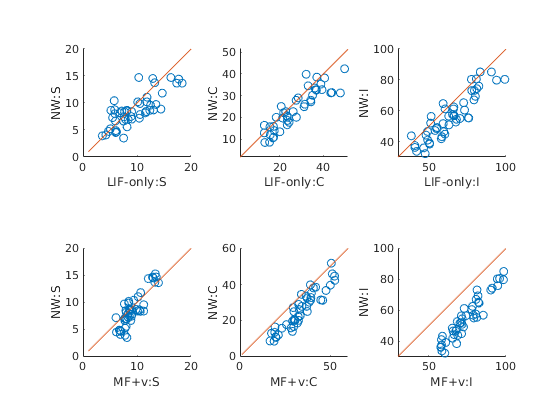

DirLDEresults(:,1) = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.S,...
    PixInptCtgr);
%ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,2)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.C,...
    PixInptCtgr);
% ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,3)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.I,...
    PixInptCtgr);

FrLDEDir = DirLDEresults(PixIndList,:);

FrNW = [FrSPixVec(PixIndList),FrCPixVec(PixIndList),FrIPixVec(PixIndList)];

figure('Name','LIF-only results')
subplot 231
scatter(FrRcdAve(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-only:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 232
scatter(FrRcdAve(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-only:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 233
scatter(FrRcdAve(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-only:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

subplot 234
scatter(FrLDEDir(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('MF+v:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 235
scatter(FrLDEDir(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('MF+v:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 236
scatter(FrLDEDir(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('MF+v:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

A figure showing all the details

L4EPixU = 1.1690e+04

L4IPixU = 9.1036e+03

LDEInd = 4971

ans = 1

L4EPixU = 1.1876e+04

L4IPixU = 8.9468e+03

LDEInd = 5055

ans = 1

L4EPixU = 1.1639e+04

L4IPixU = 8.8327e+03

LDEInd = 4970

ans = 1

L4EPixU = 1.8770e+04

L4IPixU = 1.3780e+04

LDEInd = 8031

ans = 2

L4EPixU = 1.9640e+04

L4IPixU = 1.3964e+04

LDEInd = 8370

ans = 2

L4EPixU = 1.8418e+04

L4IPixU = 1.3467e+04

LDEInd = 7861

ans = 2

L4EPixU = 2.5744e+04

L4IPixU = 1.7705e+04

LDEInd = 11003

ans = 3

L4EPixU = 2.4735e+04

L4IPixU = 1.7661e+04

LDEInd = 10581

ans = 3

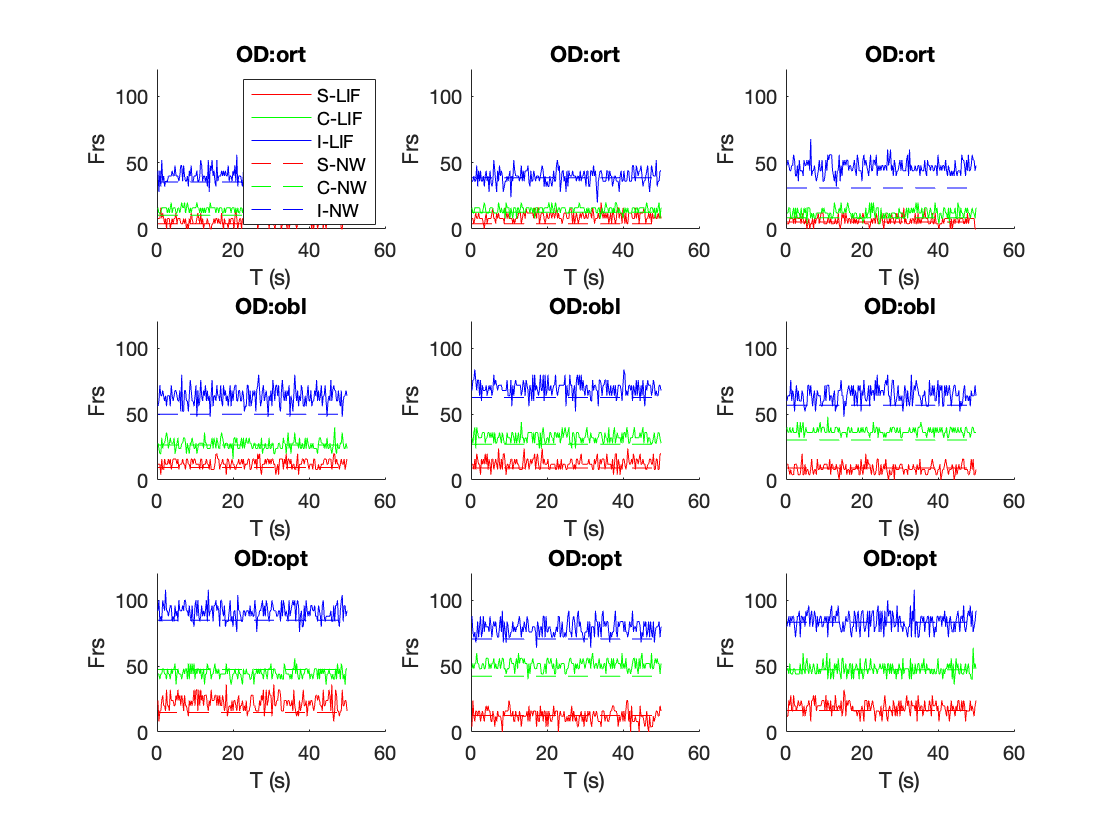

L4EPixU = 2.4739e+04

L4IPixU = 1.7621e+04

LDEInd = 10581

ans = 3

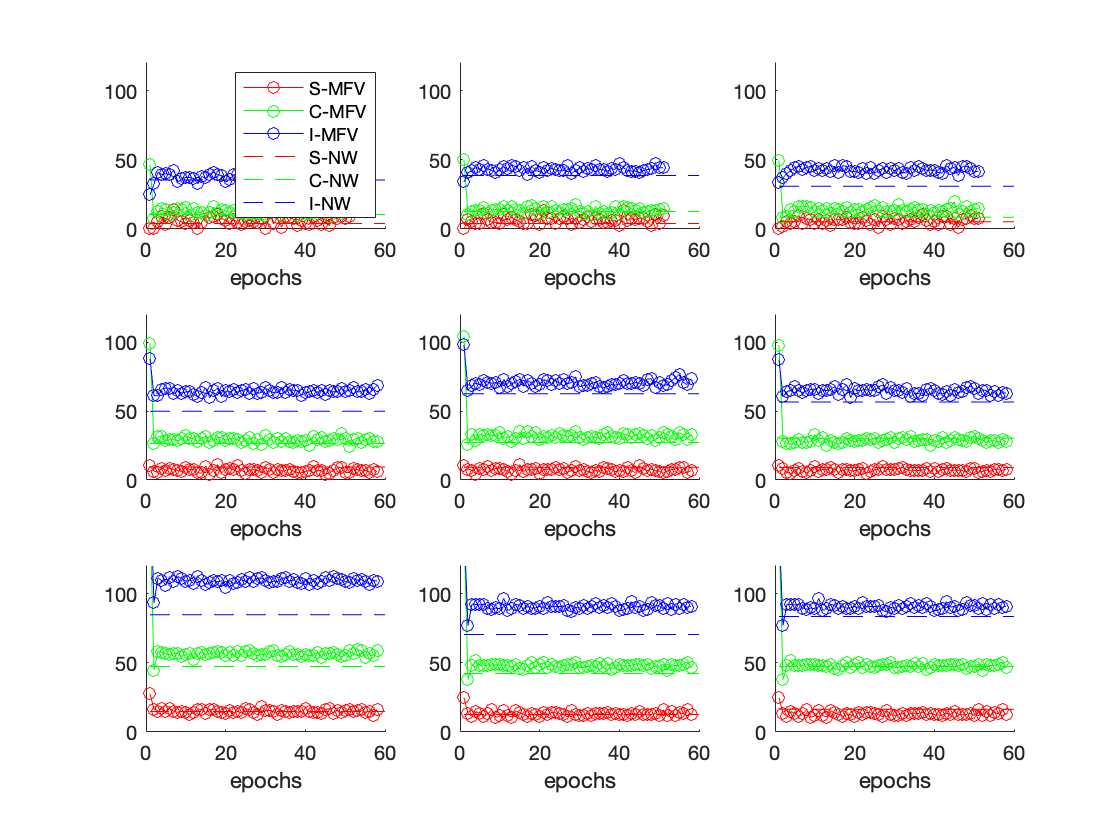

close all
TRcdSteps = 1/4:1/4:LIFSimuT/1e3;
DomName = {'ort','obl','opt'};
for PlotInd = 1:9
    SpRcdU = SpRcdAll{PlotInd};
    SpRcdU = cell2mat(SpRcdU');
    figure(1)
    % For each subplot
    subplot(3,3,PlotInd)
    hold on
    plot(TRcdSteps,SpRcdU(1,:)*LGNFreq,'r','DisplayName','S-LIF')
    plot(TRcdSteps,SpRcdU(2,:)*LGNFreq,'g','DisplayName','C-LIF')
    plot(TRcdSteps,SpRcdU(3,:)*LGNFreq,'b','DisplayName','I-LIF')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('T (s)'); ylabel('Frs'); ylim([0 120])
    title(['OD:', DomName{InputCtgrList(PlotInd)}])
    if PlotInd == 1
        legend
    end
    
    L4EPixU = L4EmfvUse(PixIndList(PlotInd))
    L4IPixU = L4ImfvUse(PixIndList(PlotInd))
    LDEInd = find(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU) == min(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU),[],'all'))
    InputCtgrList(PlotInd)
    if InputCtgrList(PlotInd) == 3
        fMFV = fLDE_OPT{LDEInd};
    elseif InputCtgrList(PlotInd) == 2
        fMFV = fLDE_OBL{LDEInd};
        
    elseif InputCtgrList(PlotInd) == 1
        fMFV = fLDE_ORT{LDEInd};
        
    end
    
    fMFV(fMFV<0) = eps;
    figure(2)
    subplot(3,3,PlotInd)
    hold on
    plot((fMFV(1,:)+fMFV(3,:))/2,'r','Marker','o','DisplayName','S-MFV')
    plot((fMFV(2,:)+fMFV(4,:))/2,'g','Marker','o','DisplayName','C-MFV')
    plot(fMFV(5,:),'b','Marker','o','DisplayName','I-MFV')
    plot(1:60,ones(size(1:60))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(1:60,ones(size(1:60))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(1:60,ones(size(1:60))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('epochs');ylim([0 120]);xlim([0 60])
    if PlotInd == 1
        legend
    end
end